# Feedback Control Basics

## Introduction

To procede with the initial lessons, you need to understand a little about feedback control.    In this lesson, a very simple description of the feedback-control approach you will use in most of the modules covering your quadcopter will be introduced.  The mathematics will be kept to a bare minimum, in order for you to develop an intuitive sense of how this works before you delve into the mathematical rigor of modern control theory.   Of course, this approach has its limitations, and they will be discussed when necessary.

## Learning Objectives

At the end of this lesson, the student will:

- Understand how a basic feedback control system works.

- How to apply a feedback control system to make a simplified model a quadcopter hover at a desired height

- Be able to identify the importance of each of the terms in a Proportional-Derivative-and-Feed-Forward Contoller

## Our Control Problem - Making a Quadcopter Hover

### Simplified Equation of Motion

For purposes of this lesson you will have a simplifed model of your drone.   The drone will be a mass.   Gravity pulls it down and the thrust from its own propellers push it up.    It is a standard convention for gravity to point in the positive z direction, so we will use that here.

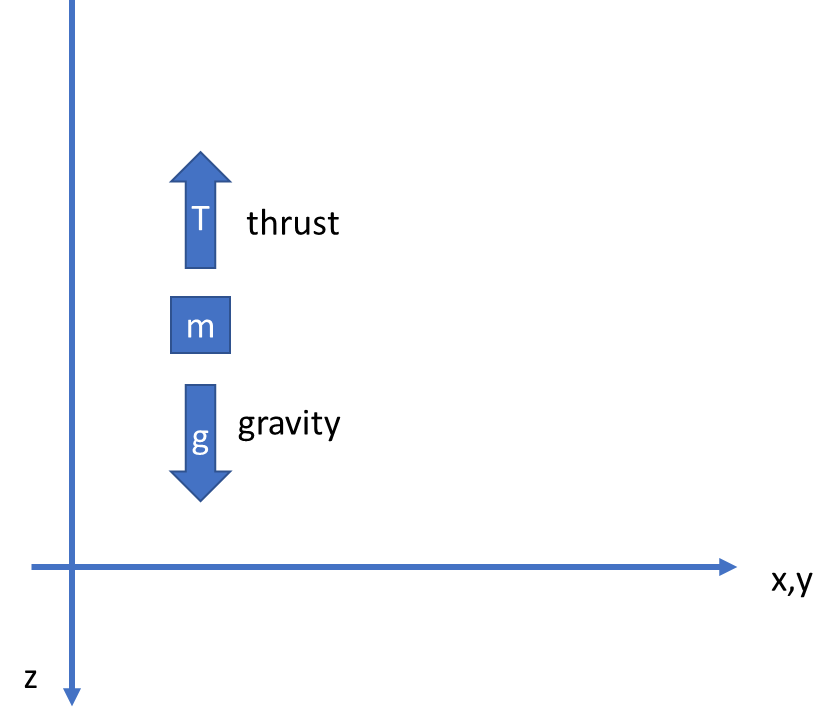

The resulting equation of motion is simply


$$m\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }z\left(t\right)=\mathrm{mg}-T\left(t,z,\frac{\textrm{d}}{\textrm{d}t}z\right)$$


with initial conditions for the position and velocity specified.

### State Equations

Where the applied thrust is could be a function of time, or position, or velocity, or any combination of the three.  This can be written in state equation form, so that we can use the differential equation solvers in MATLAB.   The result is:


$$\frac{\textrm{d}}{\textrm{d}t}\left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_z \\
g-\frac{T\left(t,z,v_z \right)}{m}
\end{array}\right\rbrack$$


with initial conditions    $\left\lbrack \begin{array}{c}
z\left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
z_0 \\
v_{\mathrm{z0}} 
\end{array}\right\rbrack$

### Problem 1   Hover at initial position

It will come as no surprise that if you start at a position and are applying thrust to compensate for gravity, that the quadcopter will stay in place.   This can be demonstrated by solving the state equations after defining the thrust function that way..

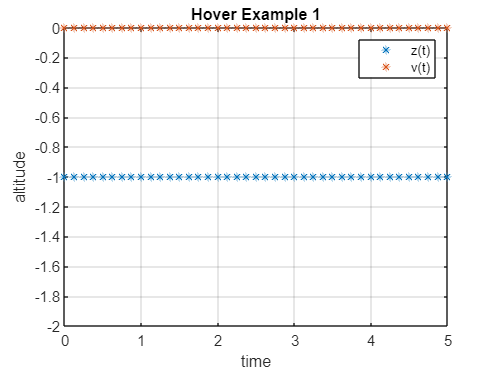

g=9.81;    % m/s^2   gravitational constant
m=0.1;     % mass in kg
z0=[-1;0];   % initial position in m and initial velocity in m/s


T=@(t,x,v)m*g;      % Thrust chosen to compensate for gravity

tspan=[0,5];        % time span of interest

F=@(t,z) g-T(t,z(1),z(2))/m;    % total force , thrust and gravity, acting on quadcopter

dzdt=@(t,z)[z(2);F(t,z)];       % State Equation

[t,z]=ode45(dzdt,tspan,z0);

plot(t,z,'*');grid on;axis([0,5,-2,0]);xlabel('time');ylabel('altitude');title('Hover Example 1');legend('z(t)','v(t)')

#### Results

Notice that the altitude remains at z=-1, which is 1 meter above the ground, since it was its intial condition and the applied thrust was precisely matched to the gravitational force.   This is a form of open-loop control.   You were able to prescribe a force to apply to achieve an objective without any knowledge that depended the state of your system, neither its altitude nor its velocity.    You will make use of this later and in these lessons, this will refer to it as a **Feed-forward Control.  ** That is to separate it from the feedback control terms that you will use next.

### Problem 2   Achieving a Hover at a position other than the initial position

If you want to start on the ground and achieve a hover at 1 meter above the ground (z=-1), you are going to have to apply some additional force.   But knowing just how much is not intuitive.  In this simple model you might be able to figure it out, but as the model develops in complexity, that approach becomes impossible.

If you just add a constant incremental force to your feed-forward force, you get the following result.

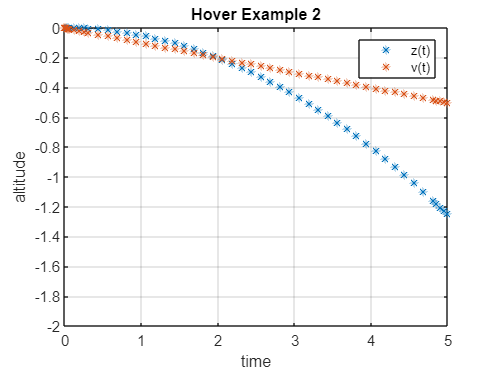

z0=[0;0];   % initial position in m and initial velocity in m/s
F2=@(t,z)F(t,z)-0.1;
dzdt=@(t,z)[z(2);F2(t,z)];
[t,z]=ode45(dzdt,tspan,z0);

plot(t,z,'*');grid on;axis([0,5,-2,0]);xlabel('time');ylabel('altitude');title('Hover Example 2');legend('z(t)','v(t)')

#### Results: Proportional Control

Fortunately the quadcopter moved in the right direction and achieved the desired altitude, but unfortunately is zoomed right past the objective position.   This makes sense - you know when you reach the desired height you will want to revert to your feed-forward thrust.   Furthermore, if you do exceed your desired height, you will want to reduce the thrust to allow the quadcopter to reduce its altitude accordingly.   A reasonable guess for the next attempt would be for the thrust to be:


$$T\left(t,z,\frac{\mathrm{d}}{\mathrm{d}t}z\right)=\mathrm{mg}+k_p \left(z_{\mathrm{desired}} -z\right)$$


Where $k_p$ is a positive constant (called the proportional constant as it is proportional to the position error) and $z_{\mathrm{desired}}$ is the desired altitude.    If you try this you will get:

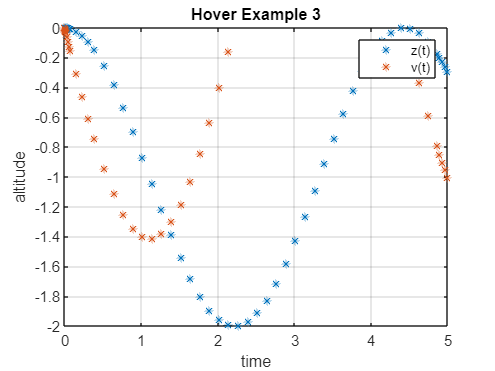

z0=[0;0];   % initial position in m and initial velocity in m/s
z_desired=-1;
kp=2;

F3=@(t,z)F(t,z)+kp*(z_desired-z(1));
dzdt=@(t,z)[z(2);F3(t,z)];
[t,z]=ode45(dzdt,tspan,z0);

plot(t,z,'*');grid on;axis([0,5,-2,0]);xlabel('time');ylabel('altitude');title('Hover Example 3');legend('z(t)','v(t)')

#### Results: Over a longer period of time

The results here are interesting and perhaps at first don't appear to be good.   But if you examine them closely, and look over a longer period of time, you will see that it achieves and average altitude that is correct, but constantly shoots by it and has to turn around.  

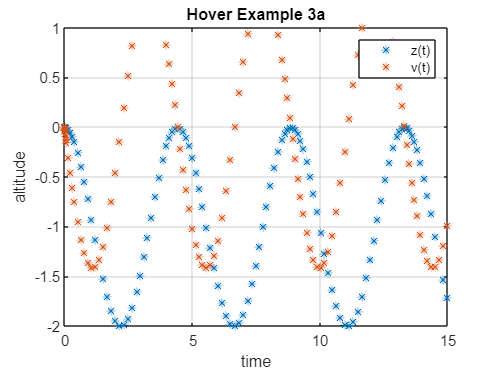

[t,z]=ode45(dzdt,[0,15],z0);
plot(t,z,'*');grid on;axis([0,15,-2,1]);xlabel('time');ylabel('altitude');title('Hover Example 3a');legend('z(t)','v(t)')

#### Results: Proportional Control + Differential Control

The next step is to control the velocity in a fashion similar to the way you controlled the altitude. A reasonable guess for the next attempt would be for the thrust to be:


$$T\left(t,z,\frac{\mathrm{d}}{\mathrm{d}t}z\right)=\mathrm{mg}+k_p \left(z_{\mathrm{desired}} -z\right)+k_d \left(v_{\mathrm{desired}} -\frac{\mathrm{d}}{\mathrm{d}t}z\right)$$


Where $k_d$ is a positive constant (called the derivative constant as it is proportional to the error of the desired derivative of position) and $v_{\mathrm{desired}}$ is the desired velocity.  For your problem, you want the desired velocity to be zero.  If you try this you will get:

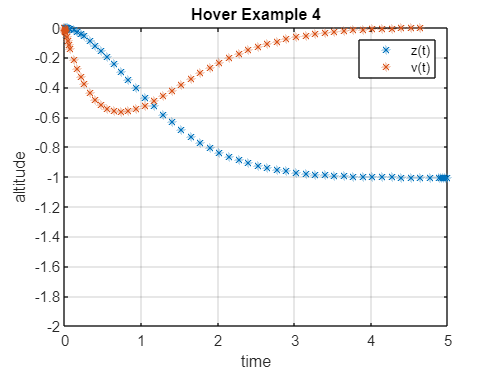

z_desired=-1;  v_desired=0;
kp=2;kd=2.5;

F4=@(t,z)F(t,z)+kp*(z_desired-z(1))+kd*(v_desired-z(2));
dzdt=@(t,z)[z(2);F4(t,z)];
[t,z]=ode45(dzdt,tspan,z0);

plot(t,z,'*');grid on;axis([0,5,-2,0]);xlabel('time');ylabel('altitude');title('Hover Example 4');legend('z(t)','v(t)')

The results are looking pretty good here.    You can see that you have achieved the desired hover in a few seconds.

### Results: Proportional Control + Differential Control + Feed Forward

The result you have now is from using a combination of open-loop control  (your feed-forward term) and closed loop control (your proportional and derivative control terms).

You can vary the proportional coefficient and the derivative coefficient to acheive the profile you like.   Essentially, increasing the proportional term will increase the speed with which you will achieve the desired altitude.   Increasing the ratio of the derivative coefficient to the proportional coefficient will reduce the amount of your quadcopter will overshoot past the desired altitude.

This example illustrates a simple case of a common control system, called PD+FF for Proportional, Derivative and Feed-Forward Control.

## Limitations to the Simple Model

The PD+FF Controller is incredibly useful and well-suited for your quadcopter.  It is not, however, applicable in all circumstances.   The problem you tried to control here was quite simple.  It was linear, you had perfect knowledge of your actual position and of the dynamics of flight.  There were no calibrations, or disturbances, or variations over time.    So be careful!    A good engineer always needs to be sure the model fits reality well enough.    

Still, as was mentioned earlier, this is a useful and robust approach for your problem in these modules and you will continue to use it throughout, as the problem becomes more complex.